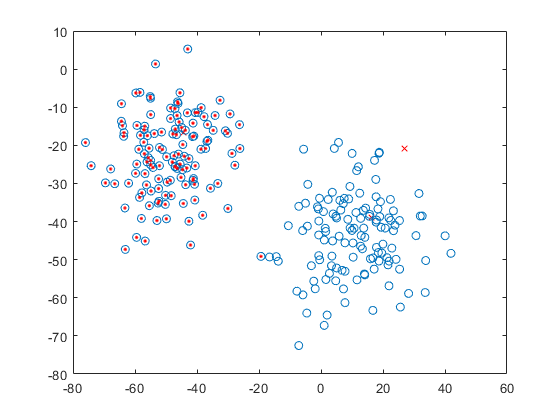

A=250;
CentrosReales=10*2*(randn(2,2)-0.5);
desviaciones=5*2*(randn(2,A)-0.5);

Puntos=CentrosReales(:,1)+desviaciones(:,1:A/2);
Puntos=[Puntos,CentrosReales(:,2)+desviaciones(:,A/2+1:end)];

plot(CentrosReales(1,:),CentrosReales(2,:),'rx')
hold on
plot(Puntos(1,:),Puntos(2,:),'o');
plot(Puntos(1,1:A/2),Puntos(2,1:A/2),'.r');

entradas=Puntos;
deseados=[ones(1,A/2),zeros(1,A/2)];

% revolver
index=randperm(A);
entradas=entradas(:,index);
deseados=deseados(:,index);
